# 粒子群优化(Particle Swarm Optimization)及其应用

By **周建山**

`jianshanzhou@foxmail.com`

优化技术是一种以数学为基础、应用于求解各类工程问题最优方案或者满意方案的技术. 美国工程院院士哈佛大学教授何毓琦(Yu-Chi Ho)教授曾指出:"任何控制与决策问题本质上均可归结为优化问题". 

在实际工程应用中，我们所面临的工程问题往往具有规模大、约束强、非线性等特点，探索一种适合大规模工程优化问题的方法称为优化理论与技术领域的前沿热点. 我们在面对实际工程问题时候，希望所设计的优化方法具有:

- 能够很好应对问题中优化目标和优化约束条件的强非线性条件，具备合理"避开"可行解空间中潜在的诸多局部极小值点的搜索能力以获得全局最优点.

- 能够很好应对问题大规模复杂性所带来的NP-hard特性，具备在限定的优化满意程度下高效的可行解搜索能力.

- 能够很好应对某些特定工程问题的多目标优化需求，对各个优化目标有较好的平衡能力.

- 能够很好应对某些特定工程问题的不确定性、随机性，具有良好的鲁棒搜索能力.

- 能够很好应对某些特定工程问题中连续型和离散型变量共存的情况，具有良好的搜索灵活性和有效性

总之，我们的"愿景"很美好:

- *具备躲避局部极小点的搜索潜力*

- *具备高效、灵活的搜索拓展能力*

- *具备鲁棒、稳定的全局优化性能*

## 粒子群优化: Particle Swarm Optimization (PSO) —— `来自大自然的启迪`

*美国****心理学家***[James Kennedy](https://en.wikipedia.org/wiki/James_Kennedy_(social_psychologist))*和****电器工程师***[Russell Eberhart](http://www.engr.iupui.edu/~eberhart/)*从鸟群觅食行为中获得灵感而提出的一种基于群体智能理论的新型演化计算技术.*

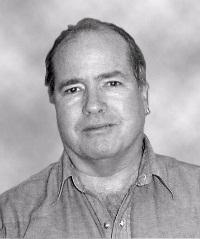  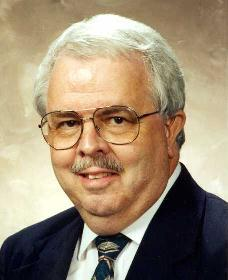

PSO中从群体生物行为到群体智能算法的类比思想:

- "优化问题的搜索空间">>>"鸟群(Swarm)的飞行空间"

- "鸟群中每一只个体(鸟)抽象为飞行空间中运动的无质量无体积的微粒子(Particle)">>>"优化问题的解空间中其中一个候选解(Candidate Solution)"

- "优化问题的解空间中的全局最优解(Global Best Solution)">>>"鸟群所要寻觅的食物所在的空间位置"

- "鸟群觅食飞行运动行为规则">>>"求解全局最优解的搜索策略"

"**鸟群觅食飞行运动行为规则**"的内在机制是一种群体协同机制——Kennedy和Eberhart研究发现：当食物不可先知地零星分布在空间某个位置，鸟群的协同觅食所带来的优势远大于对食物竞争所带来的劣势. 

群体协同的机制实现，必然依赖于两个方面: 要有"***记忆***"能力、还要有"***共享***"精神！！！

- 每个个体具有"记忆"自身已经搜索到的最佳位置、全局/邻域所有个体已经搜索到的最佳位置的能力

- 全局/邻域所有个体具有"共享"自己搜索历史经验的精神

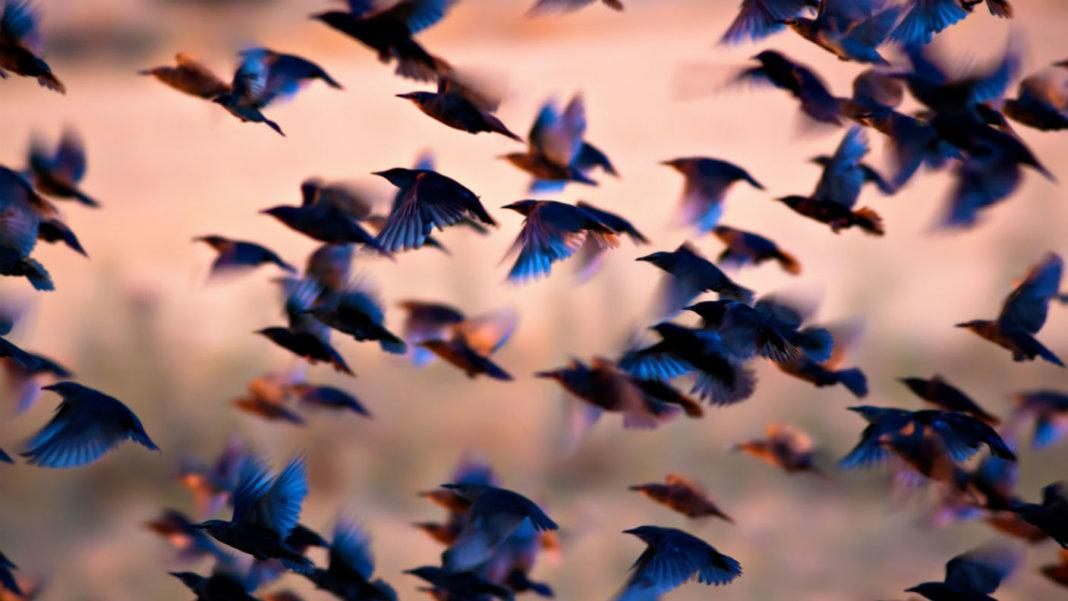

## PSO的数学模型 —— 从群体行为机制到数学建模

如何从数学角度刻画鸟群中个体觅食飞行状态呢？——采用两个参数：位置(**Position**)和速度(**Velocity**)，以描述飞鸟的行为状态. 因此，假设我们的粒子群体规模为$N$，我们自然而然地考虑到，针对一般化的$d$维搜索空间中的第$i$个粒子，其在第$t$个时刻的速度和位置分别可以用如下两个向量来表示：


$$\begin{cases}
\mathbf{X}_{i}(t)=\left[x_{i,1}(t),x_{i,2}(t),\cdots,x_{i,d}(t) \right]^{\mathrm{T}}\\
\mathbf{V}_{i}(t)=\left[v_{i,1}(t),v_{i,2}(t),\cdots,v_{i,d}(t) \right]^{\mathrm{T}}
\end{cases}$$


我们通过评价每个粒子的目标函数值(也称为"适应度(Fitness)")来评价该粒子所找到的位置的"好坏". 我们假定优化目标函数为$\mathit{fitness}=Objective(\mathbf{P})$，优化的准则是"目标函数值越大越好". 则可以利用该目标函数来评估当前$t$时刻该粒子所找到的位置的好坏，例如


$$\mathit{fitness}_{i}(t)=Objective(\mathbf{X}_{i}(t))$$


那么，从初始时刻0开始至当前$t$时刻，该粒子可以记住**到目前为止其所找到的最佳位置**. 因此，在$t$时刻，第$i$个粒子所能搜索到的最佳位置(Individual Best)可以记为


$$\mathbf{P}_{i}=\left[p_{i,1},p_{i,2},\cdots,p_{i,d} \right]^{\mathrm{T}}$$


其中，从数学角度来描述，可以这样：


$$\begin{cases}
\mathbf{P}_{i}=\mathbf{X}_{i}(\tau^\ast)\\
\tau^{\ast}=\mathrm{argmax}\limits_{\tau=0,1,2,\cdots,t}
\left\{
\mathit{fitness}_{i}(\tau)
\right\}
\end{cases}$$


经过所有粒子对自己所找到位置好坏的评估之后，整个群体在$t$时刻所发现的最佳位置(Global Best)可以记为

$\mathbf{P}_{g}=\left[p_{g,1},p_{g,2},\cdots,p_{g,d} \right]^{\mathrm{T}}$，其中，


$$\begin{cases}
\mathbf{P}_{g}=\mathbf{P}_{i^{\ast}}\\
i^{\ast}=\mathrm{argmax}\limits_{i=1,2,\cdots,N}
\left\{
\mathit{Objective}(\mathbf{P}_{i})
\right\}
\end{cases}$$


综合上面的概念，那么，PSO算法的机制可以通过如下离散更新方程来描述——亦即刻画每个粒子如何动态更新自己的位置和速度


$$1. \mathbf{速度更新:}\\
v_{i,j}(t+1) = wv_{i,j}(t)
+ c_1 r_1 \left[p_{i,j}-x_{i,j}(t)\right]
+c_2r_2 \left[p_{g,j}-x_{i,j}(t)\right]\\
2. \mathbf{位置更新:}\\
x_{i,j}(t+1) =  x_{i,j}(t)+v_{i,j}(t+1),~j=1,2,\cdots,d$$


其中，$w$表示"惯性权因子"，$c_1$和$c_2$分别表示正的加速常量，$r_1$和$r_2$分别表示在$[0,1]$区间均匀分布的随机数. 此外，通过设置粒子的速度区间$[v_{\min},v_{\max}]$和位置的范围$[x_{\min},x_{\max}]$，可以对粒子的移动进行适当约束.

此外，Clerc和Kennedy提出一种新的调整方法，引入一个压缩因子来调整上面所述的速度更新方程，他们这种方法通过选择合理的参数值，确保PSO算法的收敛性，并取消对速度的边界限制：


$$v_{i,j}(t+1) =\chi \left\{wv_{i,j}(t)
+ c_1 r_1 \left[p_{i,j}-x_{i,j}(t)\right]
+c_2r_2 \left[p_{g,j}-x_{i,j}(t)\right]\right\}\\
\chi=\frac{2}{
\left\vert
2-\varphi-\sqrt{\varphi^2-4\varphi}
\right\vert
}\\
\varphi=c_1+c_2\\
\varphi>4$$


特别地，当取$c_1=c_2=2.05$，则$\varphi=4.1$且$\chi=0.729$.

从上面粒子更新速度的方程可见，更新的机制包含三个物理内涵：

- 速度更新方程的第一部分反映了粒子当前速度对下一时刻速度的影响，将其当前的速度状态和未来的速度状态联系起来

- 速度更新方程的第二部分反映了粒子的认知模式(Cognition Modal)对下一时刻速度的影响，即粒子本身的记忆中，其当前所找到的最好的位置信息对其下一步搜索移动产生影响

- 速度更新方程的第三部分反映了群体社会模式(Social Modal)对该粒子个体下一时刻速度的影响，即群体通过信息共享促进个体改善移动搜索途径

在上述三部分的作用下，每个粒子根据自己的历史经验和群体信息共享机制，不断调整自己的位置以期搜索到问题解空间中的最优解.

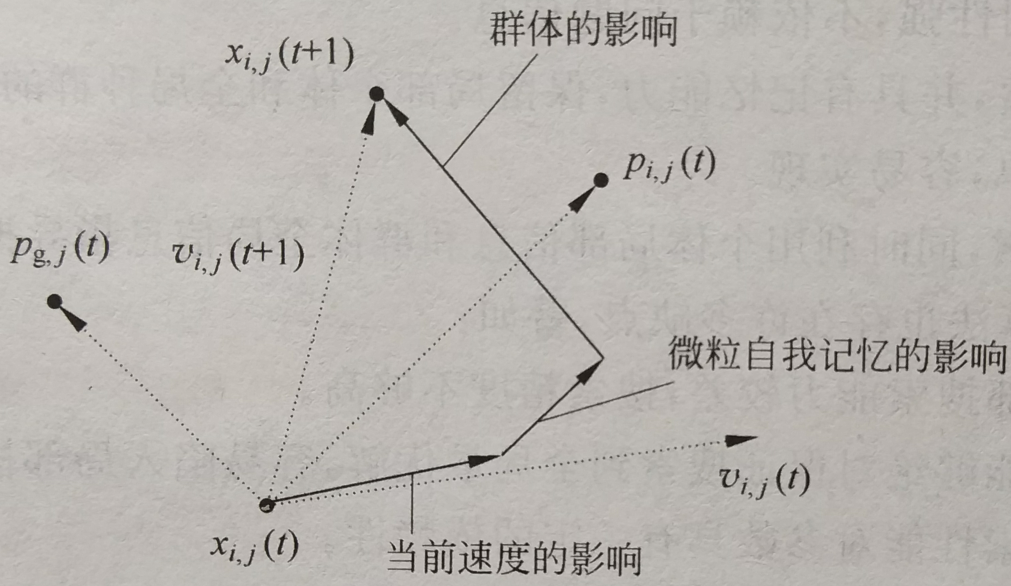

## PSO算法的基本流程 —— 从数学建模到算法设计

**步骤一**：初始化粒子群，亦即初始化每个粒子的位置和速度：$\mathbf{X}_{i}(0)$和$\mathbf{V}_{i}(0)$，置$t=0$

**步骤二**：记录每个粒子的当前位置和速度信息$\left\{
\mathbf{X}_{i}(t),\mathbf{V}_{i}(t)
\right\}$，评价每个粒子当前位置的性能并记录其到目前为止所找到的最好位置及该位置对应的目标函数值$\left\{\mathbf{p}_{i},
\mathit{Objective}(\mathbf{p}_{i})
\right\}$、比较全局粒子当前个体所能找到的最优位置对应的目标函数值，并记录当前粒子群体最优位置及其群体最优目标函数值$\left\{\mathbf{p}_{g},
\mathit{Objective}(\mathbf{p}_{g})
\right\}$

**步骤三**：更新每个粒子的速度和位置并更新其记录$\left\{
\mathbf{X}_{i}(t),\mathbf{V}_{i}(t)
\right\}
\leftarrow
\left\{
\mathbf{X}_{i}(t+1),\mathbf{V}_{i}(t+1)
\right\}$，置$t\leftarrow t+1$

**步骤四**：评价每个粒子的位置

**步骤五**：将每个粒子的位置对应的目标函数值$\mathit{Objective}(\mathbf{X}_{i}(t))$和其历史个体最优目标函数值$\mathit{Objective}(\mathbf{p}_{i})$作比较，如果当前位置的目标函数值更优，亦即$\mathit{Objective}(\mathbf{X}_{i}(t))>\mathit{Objective}(\mathbf{p}_{i})$，则分别更新该粒子个体最优位置及其目标函数值记录：$\left\{\mathbf{p}_{i},
\mathit{Objective}(\mathbf{p}_{i})
\right\}\leftarrow
\left\{\mathbf{X}_{i}(t),
\mathit{Objective}(\mathbf{X}_{i}(t))
\right\}$

**步骤六**：比较每个粒子的当前个体最优目标函数值$\mathit{Objective}(\mathbf{p}_{i})$，选出当前全局最优目标函数值$\max\limits_{i=1,2,\cdots,N}
\left\{
\mathit{Objective}(\mathbf{p}_{i})
\right\}$及其对应的粒子$i^\ast=\mathrm{argmax}\limits_{i=1,2,\cdots,N}
\left\{
\mathit{Objective}(\mathbf{p}_{i})
\right\}$的个体最佳位置$\mathbf{p}_{i^\ast}$，将$\max\limits_{i=1,2,\cdots,N}
\left\{
\mathit{Objective}(\mathbf{p}_{i})
\right\}$与历史的全局最优目标函数值$\mathit{Objective}(\mathbf{p}_{g})$作比较，如果当前较优，则更新粒子群全局最优位置及其对应全局最优函数值$\left\{\mathbf{p}_{g},
\mathit{Objective}(\mathbf{p}_{g})
\right\}\leftarrow
\left\{\mathbf{p}_{i^\ast},
\max\limits_{i=1,2,\cdots,N}
\left\{
\mathit{Objective}(\mathbf{p}_{i})
\right\}
\right\}$

**步骤七**：如果满足算法迭代终止准则，则输出$\left\{\mathbf{p}_{g},
\mathit{Objective}(\mathbf{p}_{g})
\right\}$并停止算法，否则，转向**步骤三**继续执行.

## PSO算法原型实现：基于MATLAB —— 从算法设计到编程实现

MATLAB本身的Global Optimization Toolbox提供了PSO算法模块，使用起来非常方便. 这里值得指出的是，MATLAB所提供的PSO算法和前面介绍的"原始"PSO算法不一样，为了使PSO在全局优化方面具有更好的适用性，MATLAB工具箱给出的算法对Kennedy和Eberhart最初原始算法做了改进，工程师们参考的算法改进参考的是Mezura-Montes、Coello Coello、Pedersen等人的论文. 

但是，为了增加自己对算法的理解，其实也可以不依赖于工具箱，自己动手来实现一个PSO算法原型. 例如，下面基于MATLAB做的裁剪的一个实现:

- PSO算法运行的基本参数设置：

- PSO算法终止的判断模块：

- PSO算法初始化模块：

- 评估粒子群整个群体的优化目标函数值的模块：

- PSO运行主模块：

## PSO算法原型实现：基于MATLAB —— 从算法设计到编程实现

我们通过一个具体的例子来看看PSO的应用. [DE JONG](https://www.sfu.ca/~ssurjano/dejong5.html)提出的第五个全局优化基准测试函数：


$$f(\mathbf{X})=\left(
0.002+
\sum_{i=1}^{25}
\frac{1}{i+(x_1-a_{1,i})^6+(x_2-a_{2,i})^6}
\right)^{-1}$$


其中，自变量$\mathbf{X}=[x_1,x_2]^\mathrm{T}$，函数参数为：


$$  \mathbf{a}=\left(
  \begin{array}{cccccccccc}
 -32 & -16 & 0 & 16 & 32 & -32 & \cdots & 0 & 16 & 32\\
-32 & -32 & -32 & -32 & -32 & -16 & \cdots & 32 & 32 & 32
  \end{array}
  \right)$$


我们希望求解下面的最小化问题：


$$\min_{\mathbf{X}=[x_1,x_2]^\mathrm{T}}\left\{f(\mathbf{X})\right\}\\
s.t.
\begin{cases}
x_1\in[-50,50]\\
x_2\in[-50,50]
\end{cases}$$


让我们通过二维可视化的方法来看看这个目标函数长啥样：

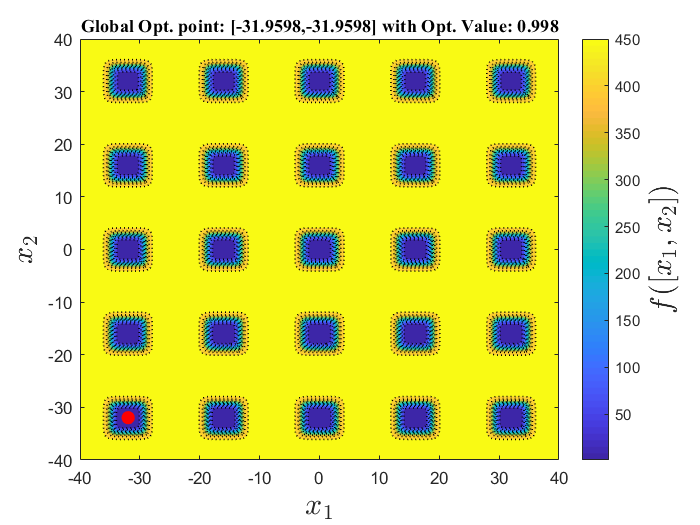

% clear workplace
clear
close all
clc

xmin = -40;
xmax = -xmin;
ymin = xmin;
ymax = xmax;
rowNum = 200;
colNum = rowNum;
[X, Y] = meshgrid(linspace(xmin, xmax, colNum), linspace(ymin, ymax, rowNum));
Z = zeros(size(X));
for i = 1:colNum
    for j = 1:rowNum
        Z(j,i) = dejong5fcn([X(j,i),Y(j,i)]);
    end
end
contourf(X,Y,Z, 'LineWidth',1,'LineColor','k','LineStyle',':');
xlabel("$x_1$", 'Interpreter','latex', 'FontSize',18);
ylabel("$x_2$", 'Interpreter','latex', 'FontSize',18);
c = colorbar('eastoutside');
c.Label.String = '$f([x_1,x_2])$';
c.Label.Interpreter = 'Latex';
c.Label.FontSize = 18;
hold on
% find the global minimum point
Xcol = X(:);
Ycol = Y(:);
[zOpt,indOpt] = min(Z(:));
xOpt = Xcol(indOpt);
yOpt = Ycol(indOpt);
plot3(xOpt,yOpt,zOpt,'o','MarkerEdgeColor','none',...
    'MarkerFaceColor','r','MarkerSize',8);
title(['Global Opt. point: [', num2str(xOpt), ...
    ',',num2str(yOpt),'] with Opt. Value: ', num2str(zOpt)],...
    'FontSize',11,'FontName','Times New Roman');
axis manual
hold off

下面我们可以利用前面编写好的PSO算法模块求解上述优化问题. 其中，分别定义MATLAB句柄函数、指定基本的决策变量数目及其边界条件等.

nvars = 2; % choose any even value for nvars
fun = @dejong5fcn;
objFcnArgs = [];
lb = [-40;-40];
ub = -lb;
options = SetupParaPSO(nvars);
options.SwarmSize = 300;
plotFlag = true;
[x, fval, exitFlag, output] = ...
    PSOalg(fun, objFcnArgs, nvars, lb, ub, options, plotFlag);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


hold on
plot3(x(1), x(2),fval,...
    'bv','MarkerSize', 8);
hold off

最终，利用PSO算法找到的最优解为：

disp(['Optimal Point of PSO: ', num2str(x)]);

Optimal Point of PSO: -31.9784     -31.9784


最优解对应的最优目标函数值为：

disp(['Optimal Value of PSO: ', num2str(fval)]);

Optimal Value of PSO: 0.998


PSO算法搜索终止的信息：

disp(output.message);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


disp(['Iteration number: ', num2str(output.iterations)]);

Iteration number: 45


disp(['Times of number of evaluating objective function: ', num2str(output.funccount)]);

Times of number of evaluating objective function: 13800


我们来进一步动态可视化整个粒子群"觅食"的行为：

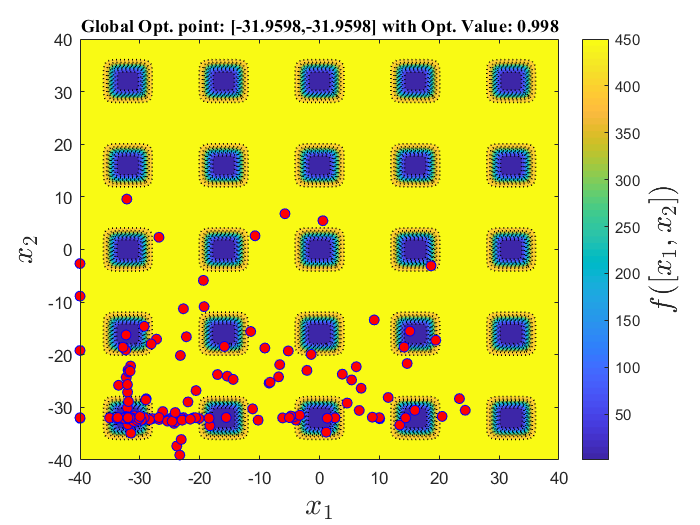

animationPlot

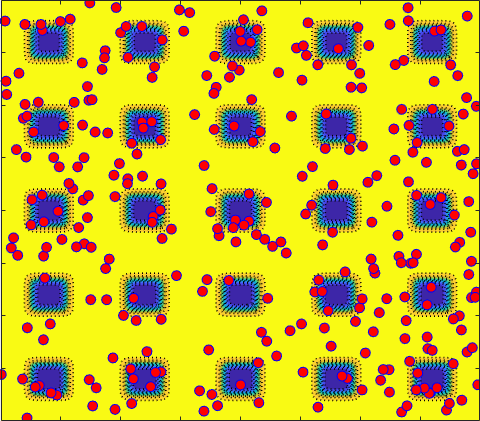

## 参考文献

- [Kennedy, J., and R. Eberhart. "Particle Swarm Optimization." Proceedings of the IEEE International Conference on Neural Networks. Perth, Australia, 1995, pp. 1942–1945.](https://ieeexplore.ieee.org/document/488968)

- [Mezura-Montes, E., and C. A. Coello Coello. "Constraint-handling in nature-inspired numerical optimization: Past, present and future." Swarm and Evolutionary Computation. 2011, pp. 173–194.](https://www.sciencedirect.com/science/article/pii/S2210650211000538)

- [Pedersen, M. E. "Good Parameters for Particle Swarm Optimization." Luxembourg: Hvass Laboratories, 2010.](https://pdfs.semanticscholar.org/a4ad/7500b64d70a2ec84bf57cfc2fedfdf770433.pdf)

- [Marini F, Walczak B. Particle swarm optimization (PSO). A tutorial[J]. Chemometrics and Intelligent Laboratory Systems, 2015, 149: 153-165.](https://www.sciencedirect.com/science/article/pii/S0169743915002117)

- [Hu X. PSO Tutorial[EB/OL]. 2006.](http://www.swarmintelligence.org/tutorials.php)